# Simulate a Mobile Robot in a Warehouse Using Gazebo testworld로변경본

This example shows how to simulate a warehouse robot in Gazebo. Gazebo enabled you to simulate a mobile robot that uses a range sensor, while executing certain tasks in a simulated environment. This example details how to use a simulator to apply the [Execute Tasks for A Warehouse Robot](docid:robotics_ug.mw_0c16e017-b9af-4684-94d7-ca6430f0aec3) example, where a robot delivers packages in a warehouse scenario. The robot makes use of the simulated range sensor in Gazebo to detect possible collisions with a dynamic environment and avoid them.

**Prerequisites**

- Download a [Virtual Machine with ROS and Gazebo](https://www.mathworks.com/ros_vm_install/v6) to set up a simulated robot.

- Review the [Execute Tasks for A Warehouse Robot](docid:robotics_ug.mw_0c16e017-b9af-4684-94d7-ca6430f0aec3) example for the workflow of path planning and navigating in a warehouse scenario.

- Review the [Control a Differential Drive Robot in Simulink and Gazebo](docid:robotics_ug.mw_ea28eff9-a4e4-4c5c-9a96-de7a21e4ed4d) example for basic steps of collecting sensor data and controlling a robot in Gazebo.

## Load Occupancy Map

Load an existing occupancy map of a small office space. Plot the start and goal poses of the vehicle on top of the map.

%load("office_area_gridmap.mat","occGrid")
load("deepracermap.mat","deepracerMap")


occGrid=deepracerMap;
%아 멍청했다 그냥 map에도 넣어줄걸
map= deepracerMap
% 2D_Grid Map의 좌측상단에 있는'저장' 버튼을 이용해 작업경로에 fig 파일로 저장해야 함

fig = openfig('deepracer.fig','visible'); % fig 파일 지정

[xi,yi] = getpts(fig); % 해당 fig 파일을 불러옴 
start = [xi,yi, -pi]; % 해당 fig 파일에서 지점을 클릭 후 Enter를 누르면 point 지정 완료

[xj,yj] = getpts(fig); % 해당 fig 파일을 불러옴
goal = [xj,yj, 0];  % 해당 fig 파일에서 지점을 클릭 후 Enter를 누르면 point 지정 완료


disp(start); % 설정한 start_point의 좌표값 출력
disp(goal); % 설정한 end_point의 좌표값 출력
 

% Show start and goal positions of robot.
hold on
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

% Show start and goal headings.
r = 0.5;
plot([start(1),start(1) + r*cos(start(3))],[start(2),start(2) + r*sin(start(3))],'r-')
plot([goal(1),goal(1) + r*cos(goal(3))],[goal(2),goal(2) + r*sin(goal(3))],'m-')
hold off

## Define State Space

Specify the state space of the vehicle using a `stateSpaceDubins` object and specifying the state bounds. This object limits the sampled states to feasible Dubins curves for steering a vehicle within the state bounds. A turning radius of 0.4 meters allows for tight turns in this small environment.

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds); % ss = stateSpaceSE2; %으로 교체해보기
ss.MinTurningRadius = 0.4;

## Plan The Path

To plan a path, the RRT algorithm samples random states within the state space and attempts to connect a path. These states and connections need to be validated or excluded based on the map constraints. The vehicle must not collide with obstacles defined in the map.

Create a `validatorOccupancyMap` object with the specified state space. Set the `Map` property to the loaded `occupancyMap` object. Set a `ValdiationDistance` of 0.05 m. This validation distance discretizes the path connections and checks obstacles in the map based on this.

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

Create the path planner and increase the max connection distance to connect more states. Set the maximum number of iterations for sampling states.

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;

Customize the `GoalReached` function. This example helper function checks if a feasible path reaches the goal within a set threshold. The function returns `true` when the goal has been reached, and the planner stops.

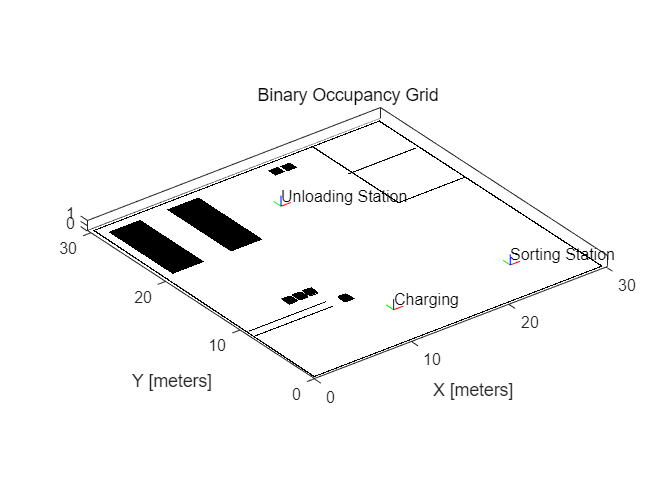

planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator for reproducible results.

rng default

[pthObj, solnInfo] = plan(planner,start,goal);

## Plot the Path

Show the occupancy map. Plot the search tree from the `solnInfo`. Interpolate and overlay the final path.

show(occGrid)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
hold off

## Customize Dubins Vehicle Constraints

To specify custom vehicle constraints, customize the state space object. This example uses `ExampleHelperStateSpaceOneSidedDubins`, which is based on the `stateSpaceDubins` class. This helper class limits the turning direction to either right or left based on a Boolean property, `GoLeft`. This property essentially disables path types of the `dubinsConnection` object.

Create the state space object using the example helper. Specify the same state bounds and give the new Boolean parameter as `true` (left turns only).

% Only making left turns
goLeft = true;

% Create the state space
ssCustom = ExampleHelperStateSpaceOneSidedDubins(bounds,goLeft);
ssCustom.MinTurningRadius = 0.4;

%흠 이거 조금 수정해봄
ss = stateSpaceSE2;

## Plan Path

Create a new planner object with the custom Dubins constraints and a validator based on those constraints. Specify the same `GoalReached` function.

stateValidator2 = validatorOccupancyMap(ss);  %(ssCustom); %에서 변경
stateValidator2.Map = occGrid;
stateValidator2.ValidationDistance = 0.01; %0.05에서 변경

planner = plannerRRT(ss,stateValidator2); %ssCustom ->ss
%planner.ContinueAfterGoalReached = true;

planner.MaxConnectionDistance = 0.5; 
planner.MaxIterations = 30000;
planner.GoalReachedFcn = @exampleHelperCheckIfGoal;

Plan the path between the start and goal. Reset the random number generator again.

rng default
%rng(100, 'twister') % repeatable result

[pthObj2,solnInfo] = plan(planner,start,goal);

## Plot Path

Draw the new path on the map. The path should only execute left turns to reach the goal.

figure
show(occGrid)

hold on

% Show the search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
pthObj2.interpolate(3000) %원래 300
plot(pthObj2.States(:,1), pthObj2.States(:,2), 'r-', 'LineWidth', 2) % 코드추가이후 길을 잘 못찾는거 같음? 일단 수정해서 굴러감

% Show start and goal in grid map.
plot(start(1), start(2), 'ro')
plot(goal(1), goal(2), 'mo')
hold off

deepracerMap.show;
hold on;
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-'); % tree expansion
plot(pthObj2.States(:,1),pthObj2.States(:,2),'r-','LineWidth',2); % draw path


## Model Overview

Open the model.

%open_system('simulateAICENRobotInGazebo.slx')
open_system('simulateAICENATRobotInGazebo2.slx')

The model can be divided into the following elements:

- **Sense:** Read data from sensors in Gazebo.

- **Schedule: **Assign packages and plan paths for robots to deliver the packages.

- **Control:** Generate commands to follow the predefined path and avoid obstacles.

- **Actuate:** Send commands to Gazebo to actuate the robot in the environment.

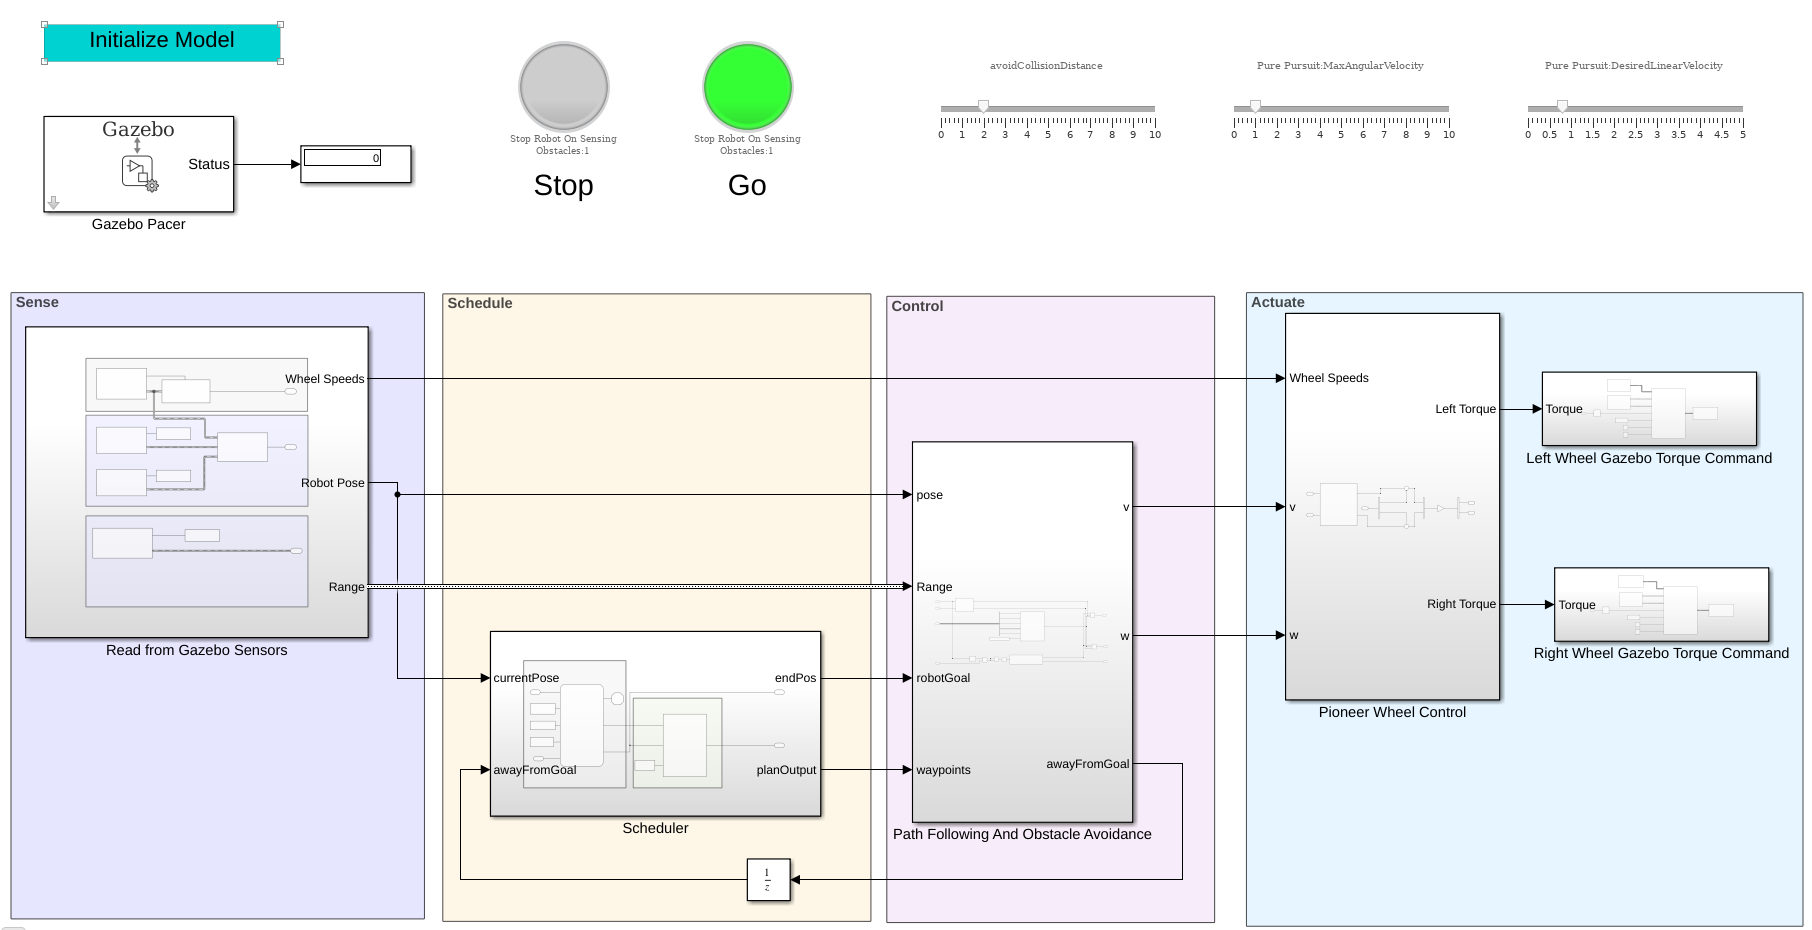

### Schedule

The robot performs the task of going between the charging station, the loading station, and the unloading station as guided by the **Scheduler**.

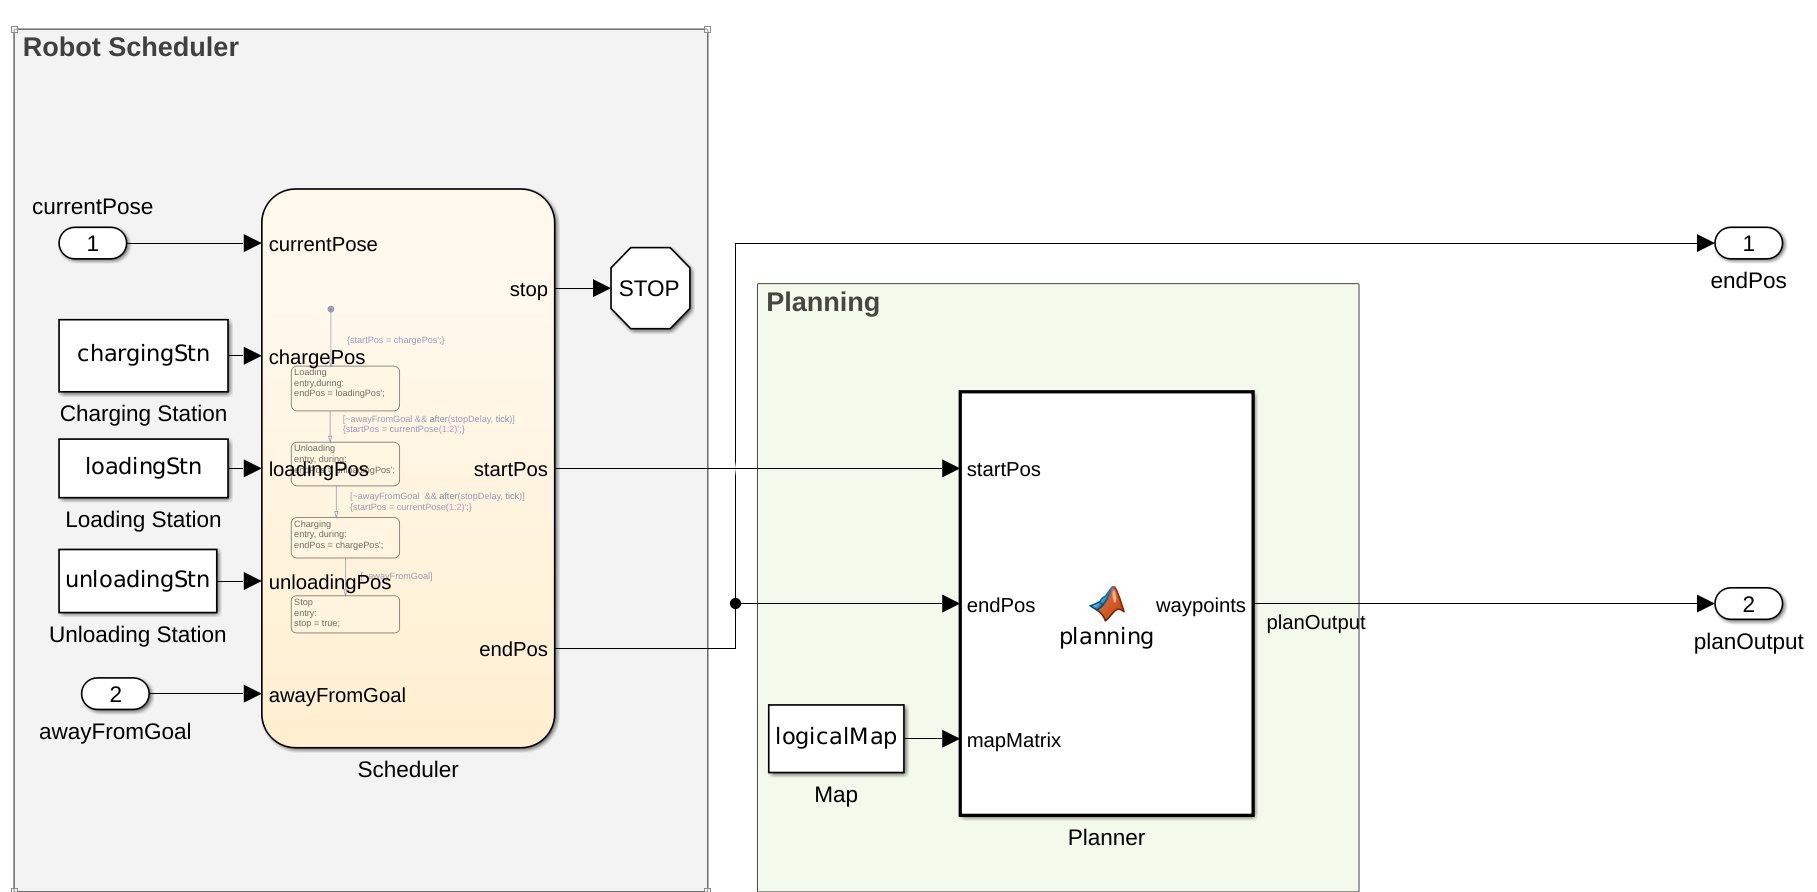

### Sense

The current robot pose, the wheel speeds, and the range sensor readings are read from the simulated environment in Gazebo. The figure below is the expanded view of the **Read From Gazebo Sensors** subsystem.

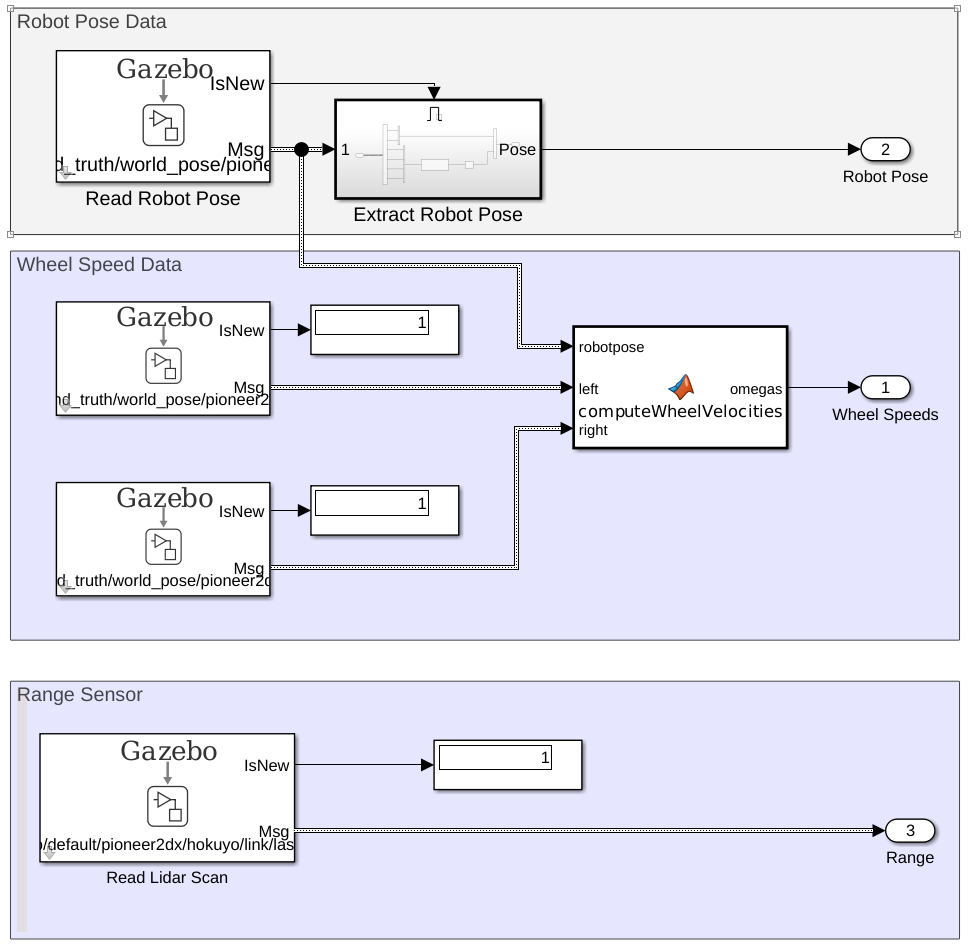

### Control

The controller generates control commands for following the waypoints using the **Pure Pursuit** block. If the range sensor on the robot detects an obstacle within the `avoidCollisionDistance` threshold, the robot stops. Also, the robot stops when gets near enough to the goal.

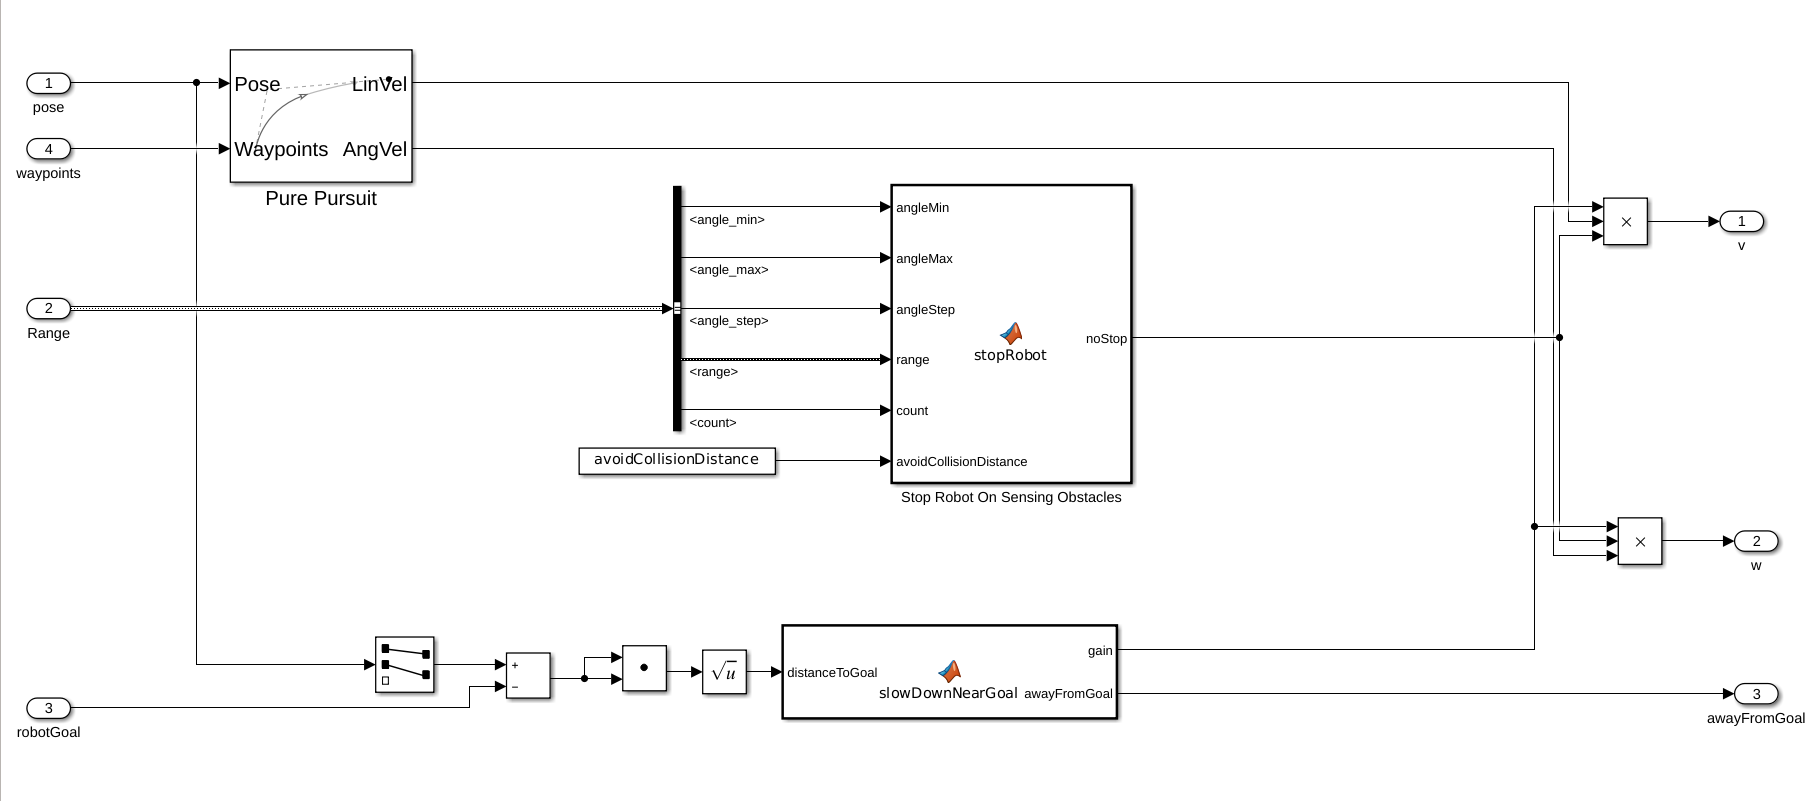

### Actuate

Based on the generated control commands, the **Pioneer Wheel Control** subsystem generates a torque value for each wheel.The torque is applied as an `ApplyJointTorque` command.

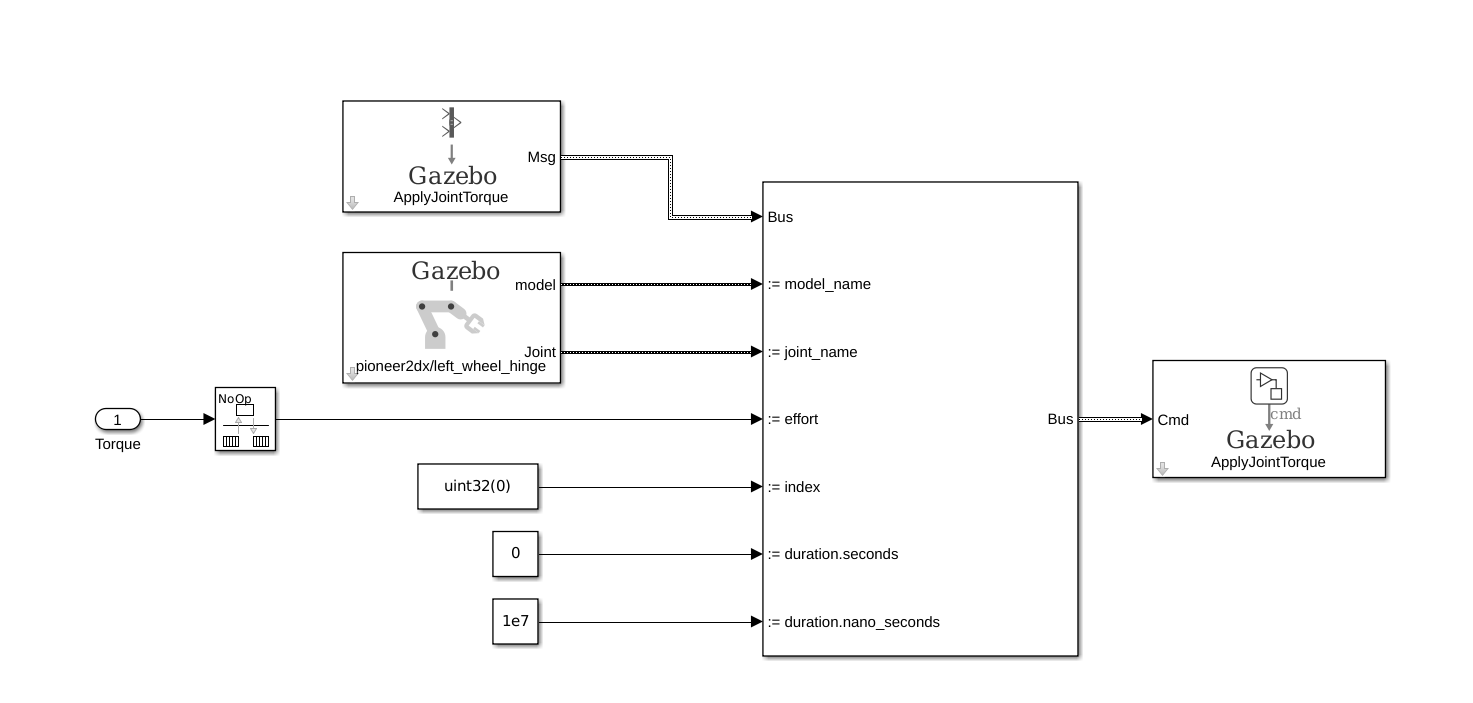

## Setup

### Warehouse Facility

Load the example map file, `map`, which is a matrix of logical values indicating occupied space in the warehouse. Invert this matrix to indicate free space, and make a `binaryOccupancyMap` object. Specify a resolution of 100 cells per meter.

The map is based off of the `warehouseExtensions.world` file, which was made using the Building Editor on the same scaling factor as mentioned below. A `.png` file for the map can be made using the `collision_map_creator_plugin` plugin to generate the map matrix. The details on how to install the plugin can be found at [Collision Map Creator Plugin](http://gazebosim.org/tutorials?tut=custom_messages&cat=transport). 

mapScalingFactor = 100;
load gazeboWarehouseMap.mat map
logicalMap = ~map;
map = binaryOccupancyMap(logicalMap,mapScalingFactor);
show(map)

 Assign the *xy*-locations of the charging station, sorting station, and the unloading location near shelves in the warehouse. The values chosen are based on the simlated world in Gazebo.

chargingStn = [12,5];
loadingStn = [24,5];
unloadingStn = [15,24];

Show the various locations on the map.

hold on;

text(chargingStn(1), chargingStn(2), 1, 'Charging');
plotTransforms([chargingStn, 0], [1 0 0 0])

text(loadingStn(1), loadingStn(2), 1, 'Sorting Station');
plotTransforms([loadingStn, 0], [1 0 0 0])

text(unloadingStn(1), unloadingStn(2), 1, 'Unloading Station');
plotTransforms([unloadingStn, 0], [1 0 0 0])

hold off;

### Range Sensor

The **Read Lidar Scan** block in the Sensing section is used to read the range values from the simulated range sensor. The `warehouseExtensions.world` file contains the details of the various models and actors (warehouse workers) in the scene. Because <`actor>` tags are static links with only visual meshes, the sensor type of the range sensor is `gpu_ray`.

Additionally, the range sensor uses 640 range, but the default is 128. This requires modification of the buses used in the in the **Read Lidar Scan** block. Load the `exampleHelperWarehouseRobotWithGazeboBuses.mat` file to get a modified bus with `Gazebo_SL_Bus_gazebo_msgs_LaserScan.range` set to 640. The modified buses were saved to a `.mat` file using the Bus Editor.

load exampleHelperWarehouseRobotWithGazeboBuses.mat

## Collision Avoidance

The actors in the world are walking a predefined trajectory. The robot makes use of a range sensor to check for obstacles within a range of 2.0 m (`avoidCollisionDistance)`  with range angles from `[-pi/10, pi/10]` Upon a non-zero reading within that range and view, the robot stops and only resumes after the range is clear. The "Stop Robot On Sensing Obstacles" function block incorporates this logic. 

While running the simulation, the **Stop **lamp turns green when the robot senses that it is good to proceed. If it has stopped the lamp turns red. 

avoidCollisionDistance = 2; 

## Simulate 

To simulate the scenario, set up the connection to Gazebo. 

First, run the Gazebo Simulator. In the virtual machine, click the **Gazebo Warehouse Robot **icon. If the Gazebo simulator fails to open, you may need to reinstall the plugin. See **Install Gazebo Plugin** **Manually** in [Perform Co-Simulation between Simulink and Gazebo](docid:robotics_ug.mw_1054c688-ce70-4924-bce3-2c404f798257).

In Simulink, open the **Gazebo Pacer** block and click **Configure Gazebo network and simulation settings**. Specify the **Network Address** as **Custom**,  the **Hostname/IP Address** for your Gazebo simulation, and a **Port** of `14581`, which is the default port for Gazebo. The desktop of the VM displays the IP address.

For more information about connecting to Gazebo to enable co-simulation, see [Perform Co-Simulation between Simulink and Gazebo](docid:robotics_ug.mw_1054c688-ce70-4924-bce3-2c404f798257).

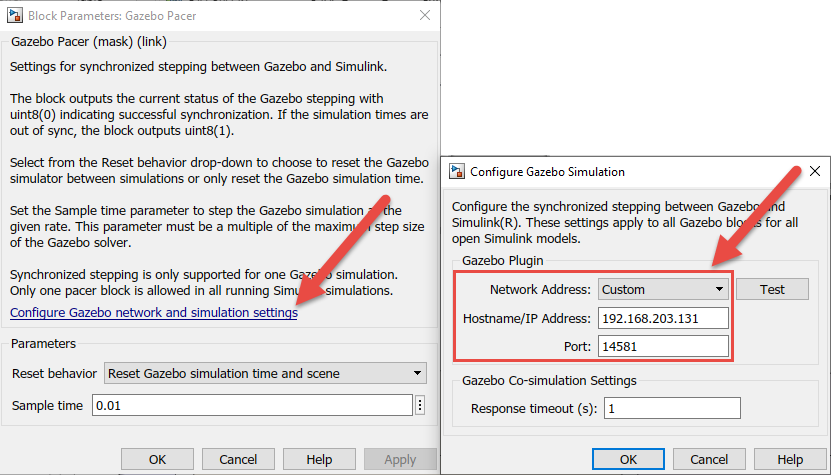

Click the **Initialize Model** button at the top of the model to intialize all the variables declared above. 

**Run** the simulation. The robot drives around the environment and stops whenever a worker gets within the defined threshold. 

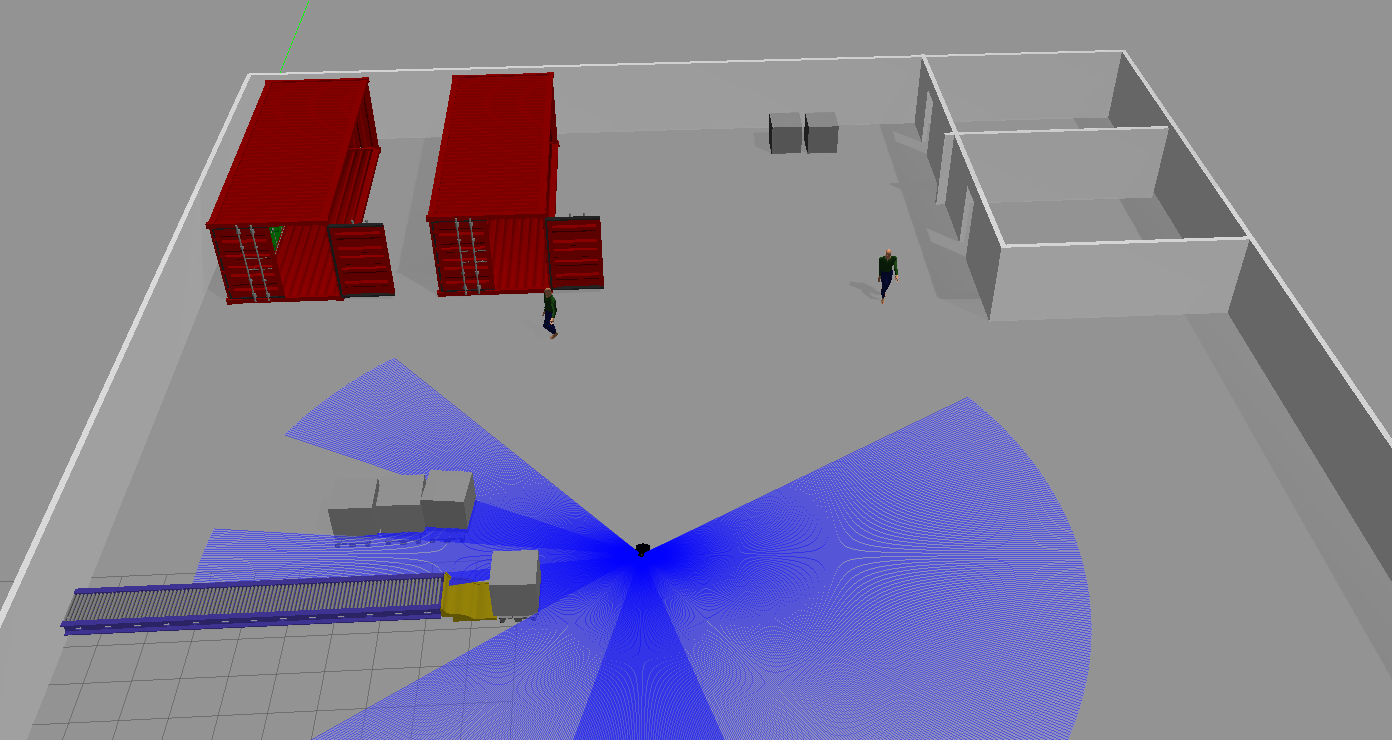

*Copyright 2019 The MathWorks, Inc.*